# Rad229 - Lecture 11:  Radial and Spiral Sequences

## lec11_01.m:  Circular Sampling PSF

This example calculates the Point-spread function (PSF) for sampling a circular region (rather than rectangular) in kspace.  It is a simple Fourier transform of 1s.

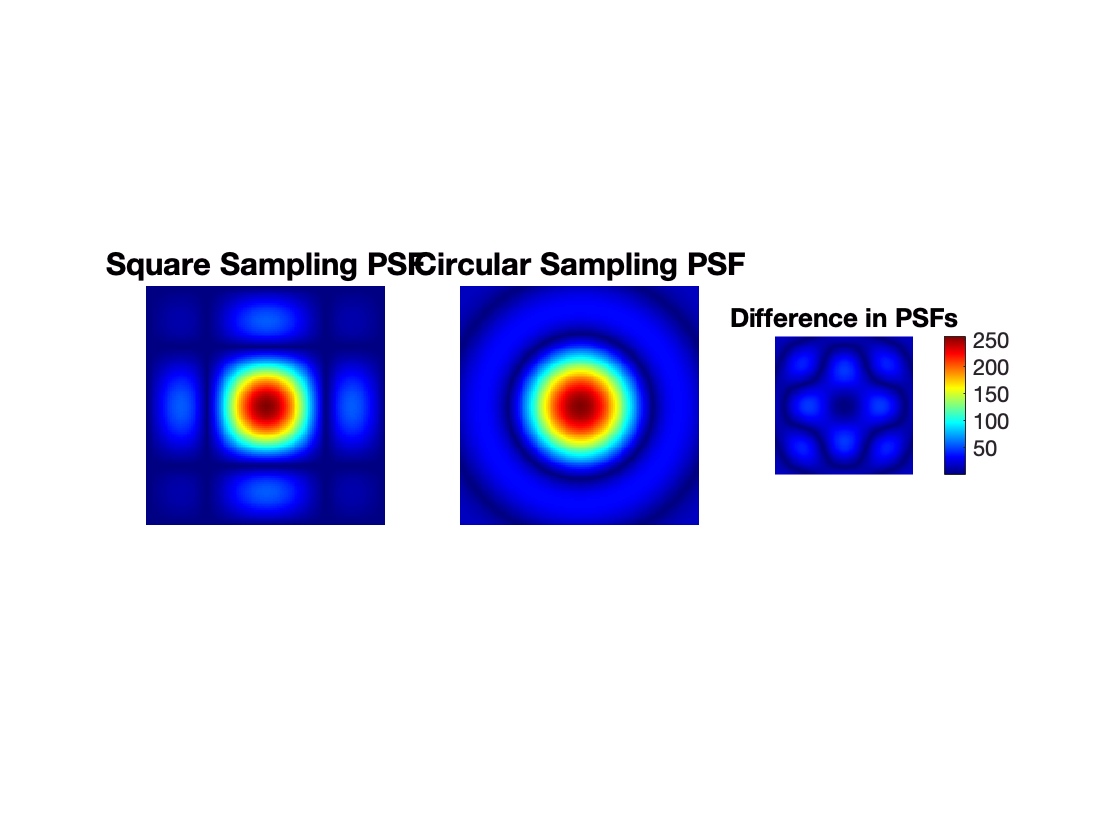

% Lecture 11, Example 01
%
% Circular vs square PSF

N = 256;        % Image
No= 32;         % oversample to interpolate PSF

kcirc = circ(N*No,N/2);
krect = 0*kcirc;
krect(N*No/2-N/2+1:N*No/2+N/2, N*No/2-N/2+1:N*No/2+N/2 )=1;

% -- FFTs
prect = ft(krect);
pcirc = ft(kcirc);

% -- Normalize & Crop
prect = cropim(prect / max(abs(prect(:))),4*No,4*No);
pcirc = cropim(pcirc / max(abs(pcirc(:))),4*No,4*No);

set(0,'defaultAxesFontSize',12);        % Default font sizes)

subplot(1,3,1);
dispim(prect);
dispim(prect,0,1); title('Square Sampling PSF');
axis off;

subplot(1,3,2);
dispim(pcirc,0,1); title('Circular Sampling PSF');
axis off;

subplot(1,3,3);
dispim(prect-pcirc,0,1); title('Difference in PSFs');
axis off;
colorbar;

colormap('jet');

## lec11_02.m:  Radial Sampling and PSF

This is a simple example of PSF calculation for radial imaging.  Note that for full sampling we really need π/2*N, so for example Ns=50 (spokes) and N=200, means about 6x undersampling, so the FOV is about 1/6 what it should be.

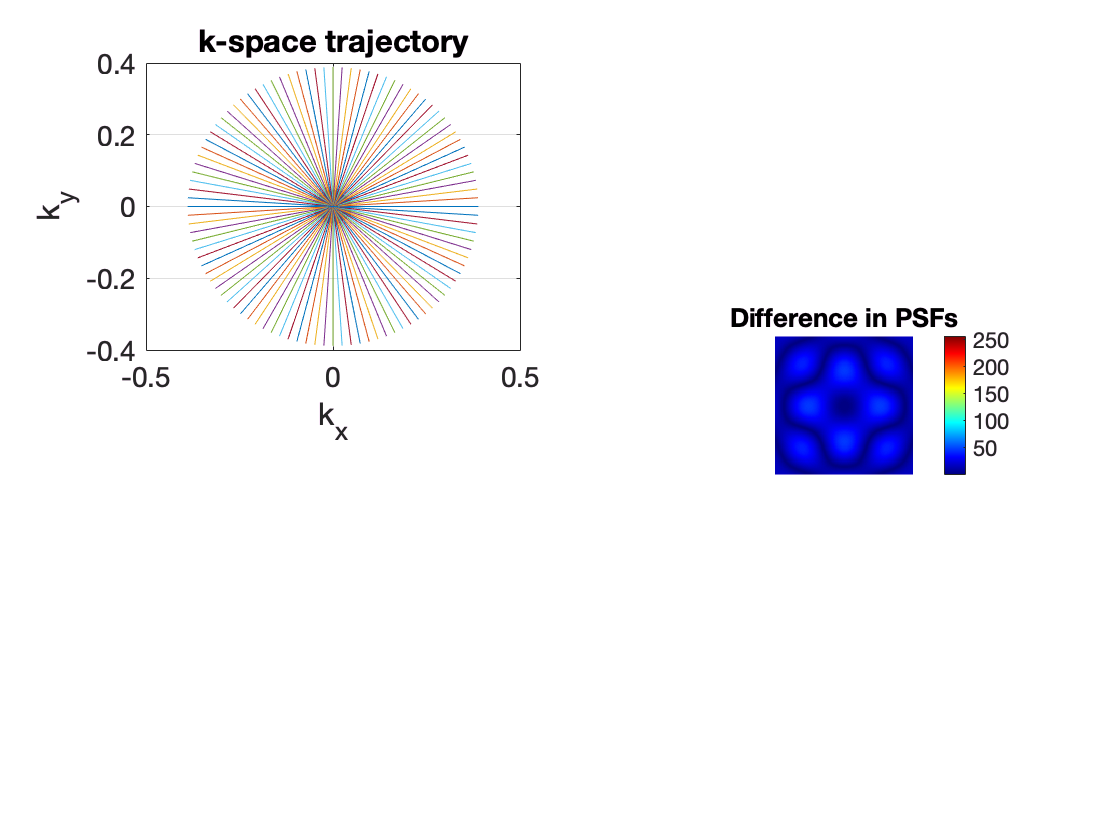

% Lecture 11, Example 02
%
% Radial PSF
%
% -- Sample in inverse pixels (k from -0.5 to 0.5)
N=200;                          % samples along readout
Ngrid=256;                      % grid (and image) points
kproj = ([1:N]-0.5-N/2)/N;      % k from -.5 to 0.5
kproj = kproj*N/Ngrid;          % scale so PSF fills FOV
kdcf = abs(kproj);              % Density compensation (1/kr)

ksamps = ones(size(kproj));     % Sample all 1s for PSF
        
Ns = 50;                        % 150 spokes (need ~300) for full sampling
kangs = pi*[0:Ns-1]/Ns;         % sample over 180 degrees (pi radians)

kall = kproj(:)*exp(i*kangs);   % full k-space locations
kdat = ones(size(kall));        % sample all ones
dcfall=kdcf(:)*ones(1,Ns);      % DCFs for gridding

gdat = gridmat(kall,kdat,dcfall,Ngrid); % Grid to 256 grid

psf = ft(gdat);         % PSF is simple reconstruction


set(0,'defaultAxesFontSize',14);        % Default font sizes
subplot(2,2,1);                          
plot(kall);                                     % Nice plot of k-space  
lplot('k_x','k_y','k-space trajectory');        % Label plot

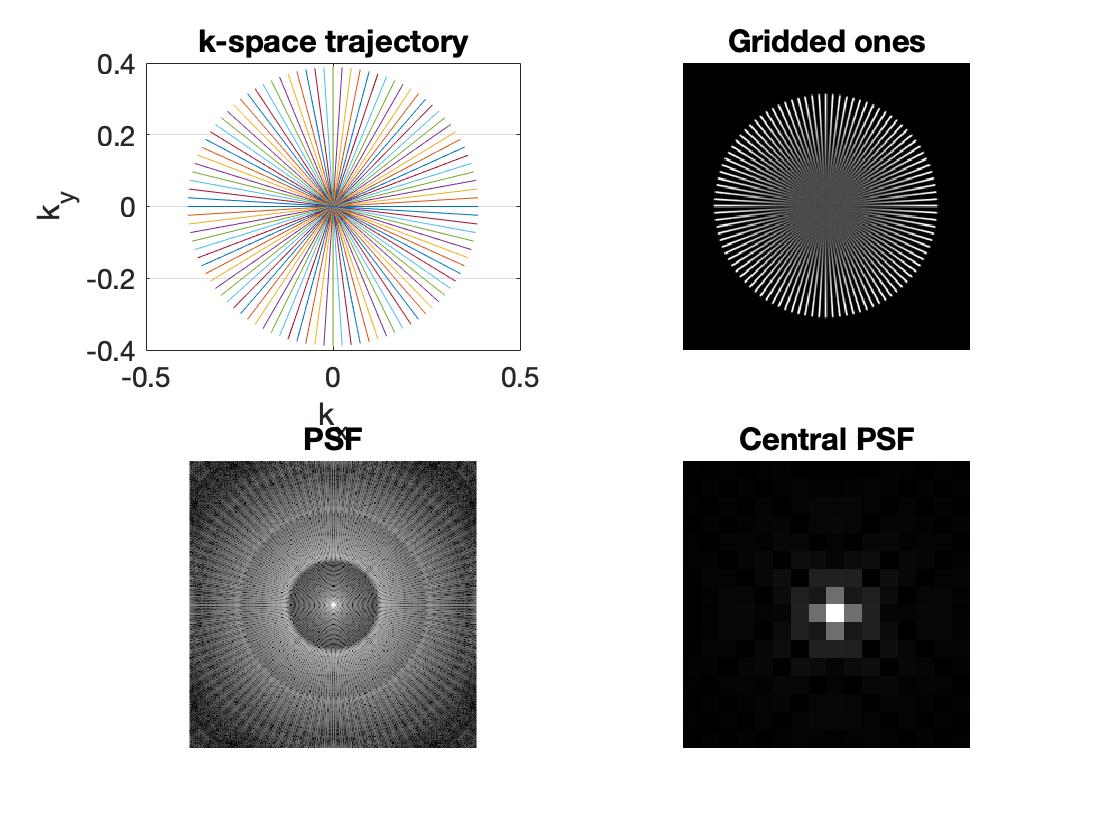


subplot(2,2,2);                                 
dispim(gdat);   axis off; title('Gridded ones');  % Display gridded k-locs

subplot(2,2,3);
dispim(log(1+abs(psf))); axis off; title('PSF');  % PSF, log scale

subplot(2,2,4); 
dispim(cropim(psf,16,16));      % central PSF (linear scale);
axis off; title('Central PSF');

Exercises:

1) Add some off-resonance phase and re-plot the PSF

2) Change the off-resonance to what it would be for radial-out and re-plot the PSF

3) Increase the number of spokes and see how the PSF changes

lec11_03.m:  Golden-Angle Sampling

This example shows the change in PSF as the temporal sampling window increases.

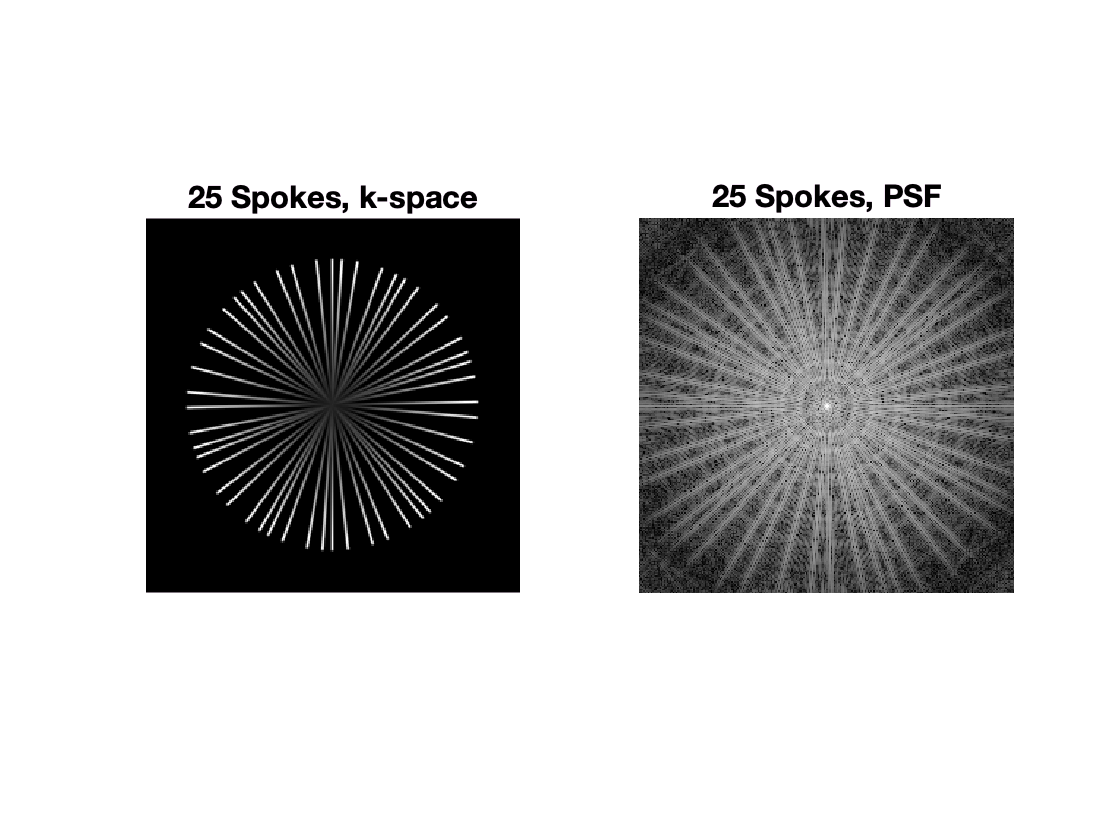

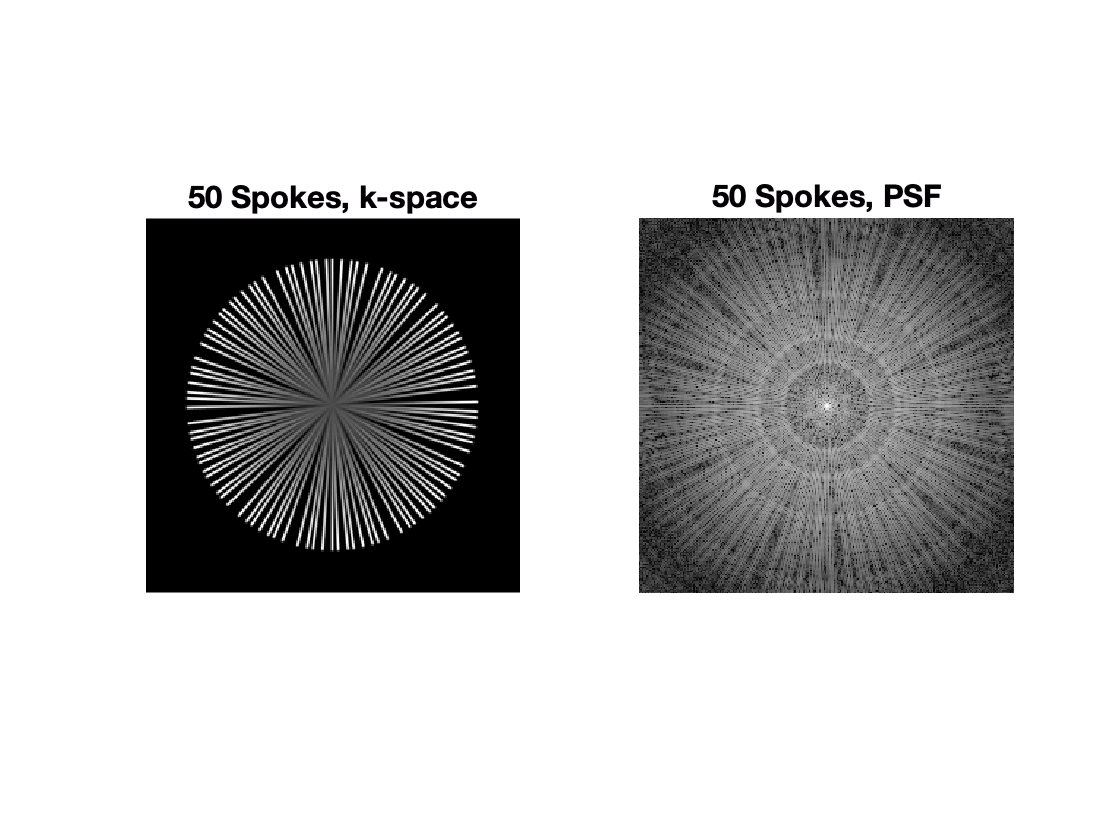

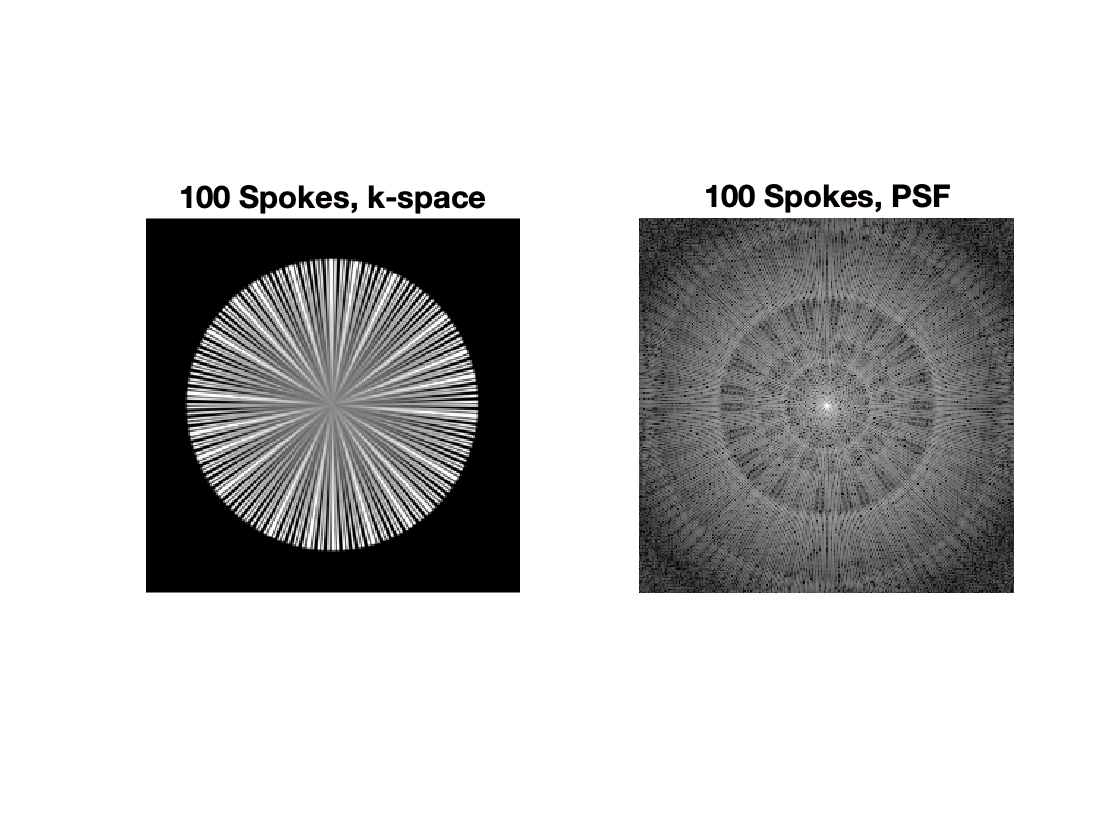

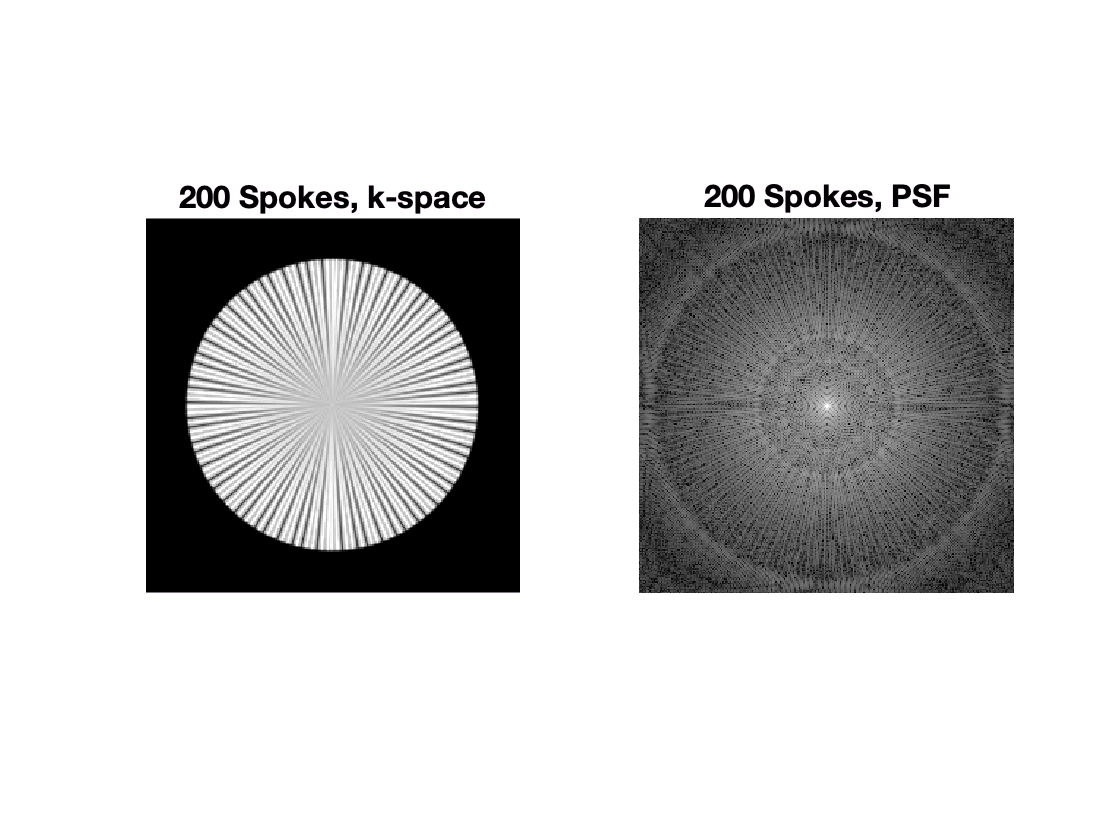

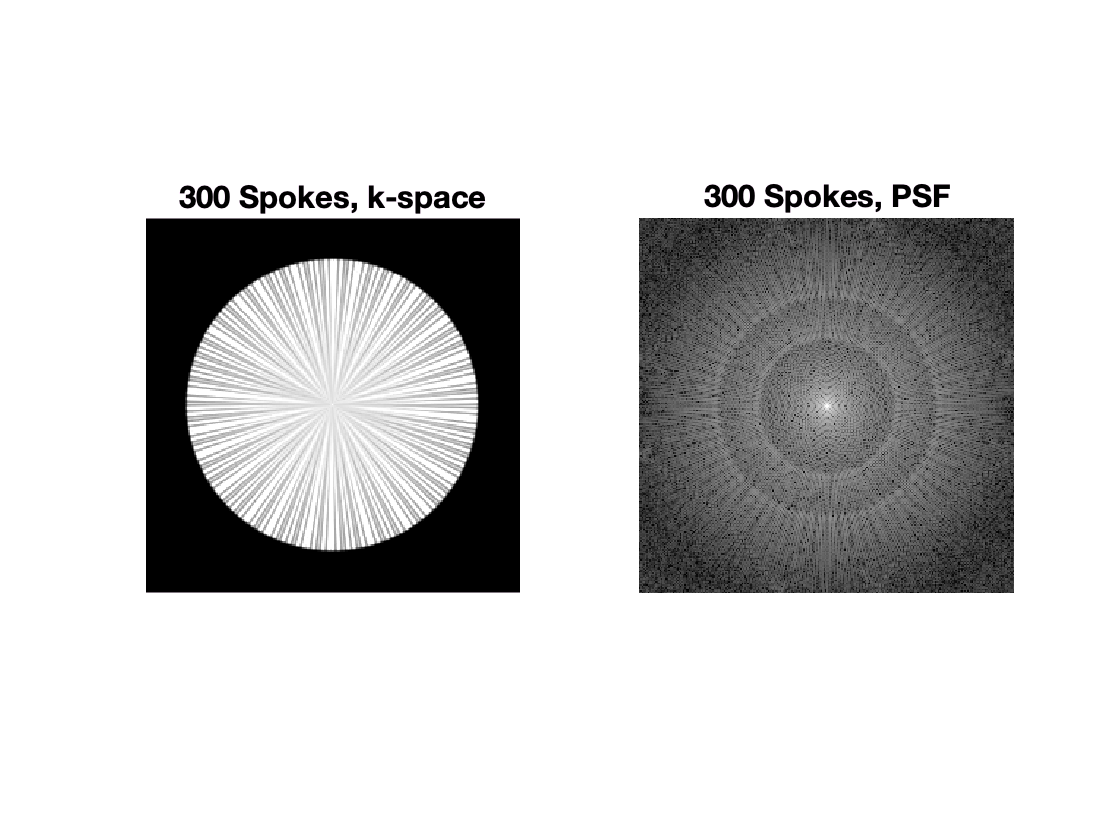

% Lecture 11, Example 03
%
% Radial PSF, with golden-angle sampling
%
% -- Sample in inverse pixels (k from -0.5 to 0.5)
N=200;                          % samples along readout
Ngrid=256;                      % grid (and image) points
kproj = ([1:N]-0.5-N/2)/N;      % k from -.5 to 0.5
kproj = kproj*N/Ngrid;          % scale so PSF fills FOV
kdcf = abs(kproj);              % Density compensation (1/kr)

ksamps = ones(size(kproj));     % Sample all 1s for PSF
        
Ns = 300;                       % (need ~300) for full sampling
ga = 2*pi/(sqrt(5)+1);          % golden angle, about 111 deg.
kangs = [0:Ns-1]*ga;            % sample with golden angle increment.

kall = kproj(:)*exp(i*kangs);   % full k-space locations
kdat = ones(size(kall));        % sample all ones
dcfall=kdcf(:)*ones(1,Ns);      % DCFs for gridding

% -- Plot a few combinations

Twin=[25 50 100 200 300];       % temporal window (#spokes)
Nc = length(Twin);              

set(0,'defaultAxesFontSize',14);        % Default font sizes
for t=1:length(Twin)
  tw=[1:Twin(t)];
  gdat = gridmat(kall(:,tw),kdat(:,tw),dcfall(:,tw),Ngrid);     % grid subset
  psf = ft(gdat);               % PSF is simple reconstruction
  figure(t);
  subplot(1,2,1);
  dispim(gdat); axis off; 
  tt=sprintf('%d Spokes, k-space',Twin(t)); title(tt);
  subplot(1,2,2); 
  dispim(log(1+abs(psf))); axis off;                    %-- PSF, log scale
  tt=sprintf('%d Spokes, PSF',Twin(t)); title(tt);        
end;

## lec11_04.m:  Spiral and Gridding

%
%       Example of spiral design, sampling, and reconstruction
%
%

% -- Design spiral waveform
FOV = 24;
rmax = 5;       % 5cm^(-1).  1mm resolution.

Fcoeff = FOV;   % Uniform density
N = 120;                % Interleaves
smax = 15000;   % G/cm/s
gmax = 5;       % G/cm
T = .000004;    % 

[k,g,s,time,r,theta] = vds(smax,gmax,T,N,Fcoeff,rmax);

vds.m
100 points, |k|=0.078515
200 points, |k|=0.289752
300 points, |k|=0.537463
400 points, |k|=0.781167
500 points, |k|=1.018513
600 points, |k|=1.248649
700 points, |k|=1.471276
800 points, |k|=1.686497
900 points, |k|=1.894290
1000 points, |k|=2.087665
1100 points, |k|=2.266530
1200 points, |k|=2.433626
1300 points, |k|=2.590943
1400 points, |k|=2.739976
1500 points, |k|=2.881881
1600 points, |k|=3.017569
1700 points, |k|=3.147777
1800 points, |k|=3.273107
1900 points, |k|=3.394060
2000 points, |k|=3.511057
2100 points, |k|=3.624458
2200 points, |k|=3.734570
2300 points, |k|=3.841659
2400 points, |k|=3.945959
2500 points, |k|=4.047674
2600 points, |k|=4.146985
2700 points, |k|=4.244054
2800 points, |k|=4.339022
2900 points, |k|=4.432021
3000 points, |k|=4.523167
3100 points, |k|=4.612564
3200 points, |k|=4.700309
3300 points, |k|=4.786490
3400 points, |k|=4.871186
3500 points, |k|=4.954472


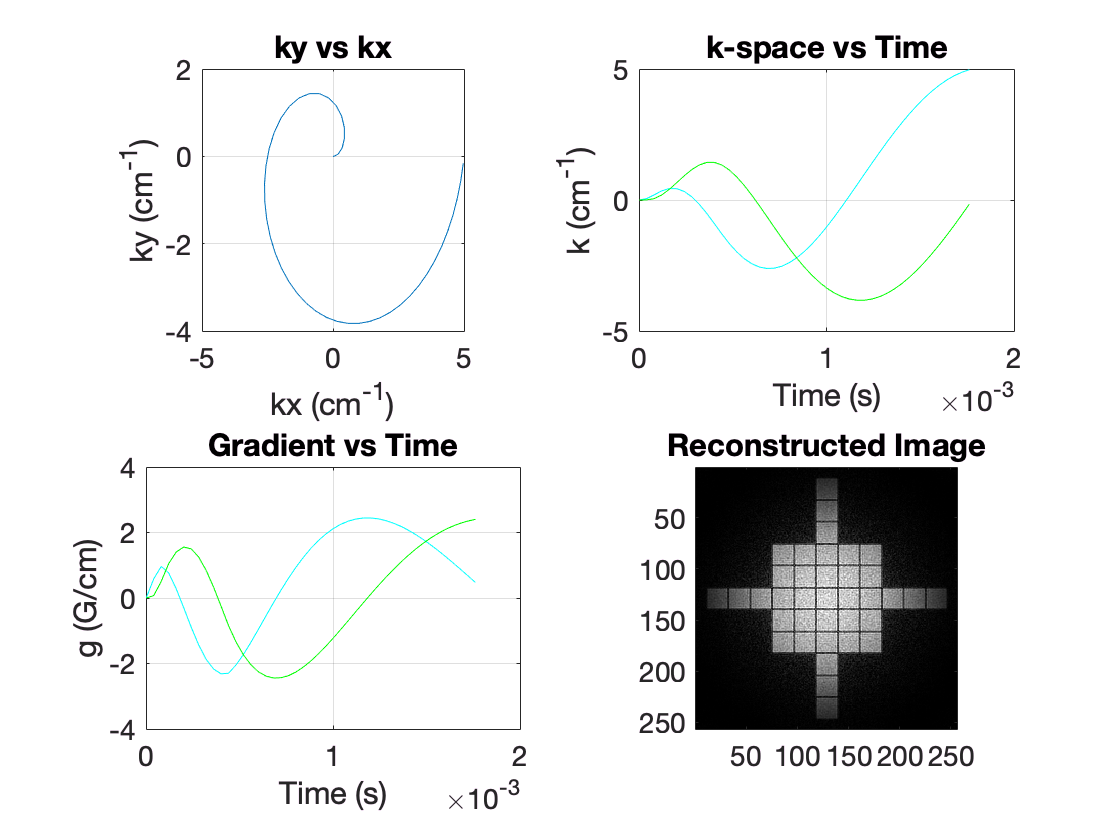



% -- Duplicate Interleaves and calculate density compensation

srot = exp(i*pi*2*[0:N-1]/N);   % Vector to Duplicate and rotate interleaves
sdup = ones(1,N);               % Vector to duplicate   

ksp = k(:)*srot;        % k-space in cm^{-1}    

dcf = vecdcf(g,k);      % Vector DCF appoximation, works well for spiral
dcf = dcf(:)*sdup;      % Duplicate for all interleaves


% -- Generate Sample Data (Array of squares)

[cx,cy] = meshgrid(2*[-2:2],2*[-2:2]);
centers = [cx(:)+i*cy(:); [-10; -8; -6; 6; 8; 10]; i*[-10; -8; -6; 6; 8; 10]]; 
kdata = ksquare(centers,1.9,ksp,T,100); % k-space data, 100Hz off-resonance
[m,n] = size(kdata);

kdata = kdata + (randn(m,n) + i*randn(m,n))/10; % Add some noise

% -- Reconstruct Image

kgrid = ksp * (240/256) * (0.5/5);      % Scale to inverse pixels
                                        % 240cm FOV/ 256 pixels * 
                                        % 0.5 inv-pixels / 5 cm^(-1)

dat = gridmat(kgrid(:),kdata(:),dcf(:),256);    % Grid data
im = ft(dat);                                   % FFT to image

dispim(im);                     % Display image
title('Reconstructed Image');   % Image


disp('Note the roll-off of the image');

Note the roll-off of the image


disp('Try changing the noise amplitude');

Try changing the noise amplitude
